### 4. Αποκατάσταση Εικόνας – Αποσυνέλιξη

Εισάγουμε gaussian θόρυβο με ώστε να έχει λόγο σήματος προς θόρυβο ( SNR ) = 10dB και με χρήση του φίλτρου wiener επιδιώκεται να απομακρυνθεί σε 2 περιπτώσεις 

- Γνωρίζοντας την φασματική πυκνότητα ισχύος του θορύβου

- Κάνοντας μία εκτίμηση της φασματικής πυκνότητα ισχύος του θορύβου

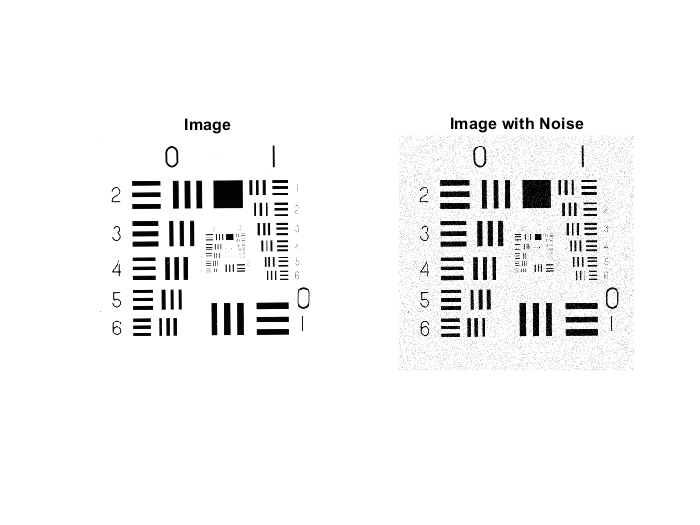

clc
clear all
x = imread('images\4\chart.tiff');
snr=10;
x=im2double(x);
m=mean(x,'all');
var_gaus=(m/10^(snr/10));
white_noise=m/10*randn(size(x));
x_with_noise=x+white_noise;

figure();
subplot(1,2,1);
imshow(x);
title(sprintf("Image"));
subplot(1,2,2);
imshow(x_with_noise);
title(sprintf("Image with Noise"));

***ΠΗΓΗ STACK EXCHANGE SIGNAL PROCESSING***

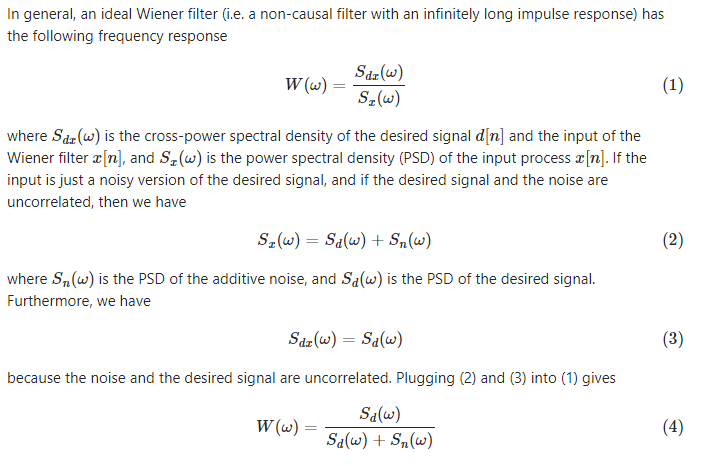

'Αρα η συνάρτηση μεταφοράς του **Wiener φίλτρου **εξαρτάται - δίνεται από τη διαίρεση της Φασματικής πυκνότητας ισχύος του σήματος / ( το άθροισμα της ΦΠΙ σήματος + ΦΠΙ θορύβου).

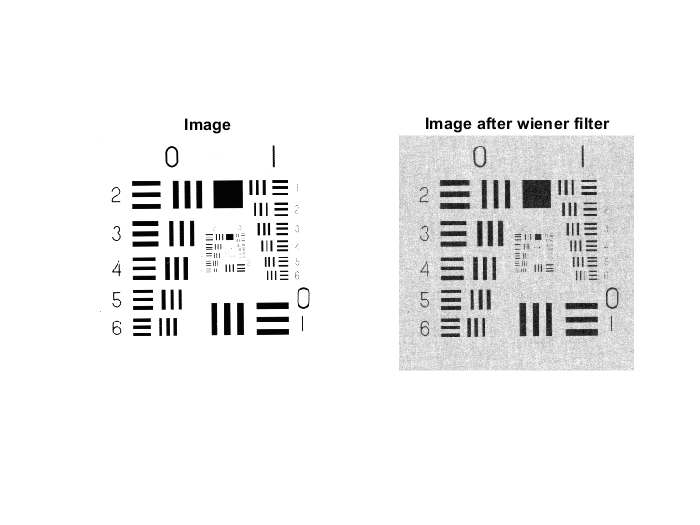

Sd=log10(abs(fft2(x)).^2 );
Sn=log10(abs(fft2(white_noise)).^2 );
Wiener=Sd./(Sd+Sn);
X=fft2(x_with_noise);
x_filtered=X.*Wiener;
x_filtered=real(ifft2(x_filtered));
figure()
subplot(1,2,1);
imshow(x);
title(sprintf("Image"));
subplot(1,2,2);
imshow(x_filtered);
title(sprintf("Image after wiener filter"));

2) Στην περίπτωση που δεν ξερουμε την ισχύ του θορύβου. Πρέπει να κάνω μια προσέγγιση ως εξής : γνωρίζω ότι ο αφού κάνω δυσδιάστατο fourier στο σήμα που έχει προστεθεί και λευκός θόρυβος τότε η επίδραση του θορύβου φαίνεται κυρίως στις υψηλές συχνότητες δηλαδή στο πάνω δεξιά κομμάτι του πίνακα x_with_noise2dfft. . Άρα εφαρμόζω έναν παράθυρο μεγέθους 32χ32 η 64χ64 στο πάνω δεξιά κομμάτι του πίνακα x_with_noise και βρίσκω ένα μέσω όρο των πυκνοτήτων ώστε εν τέλη να βρω ένα estimation για την Φασματική Πυκνότητα Ισχύος του θορύβου Pn. Θεωρούμε Px_with_noise=Px+Pnoise.  Άρα σύμφωνα με τον τύπο στο προηγούμενο ερώτημα παίρνουμε.

**H=(Px_with_noise-Estimation) / Px_with_noise**

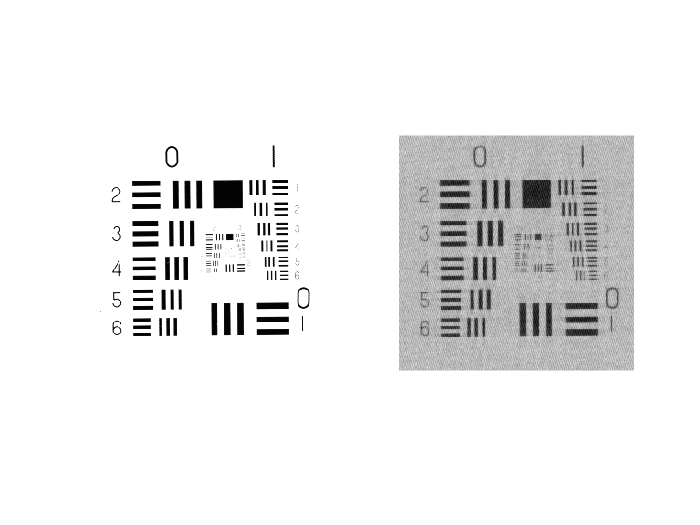


Px_with_noise=log10(abs(fftshift(fft2(x_with_noise))).^2 );
%Px_with_noise=log10(abs(fft2(x_with_noise)).^2 );
noise_window=Px_with_noise(192:256,192:256); % 64x64 megethous parathuro
Estimation=mean(noise_window,'all');
Px_with_noise=log10(abs(fft2(x_with_noise)).^2 );
Wiener=(Px_with_noise-Estimation)./Px_with_noise;
x_filtered=fft2(x_with_noise).*Wiener;
x_filtered=real(ifft2(x_filtered));
figure();
subplot(1,2,1);
imshow(x);

subplot(1,2,2);
imshow(x_filtered);

ΜΕΡΟΣ Β

Εισάγουμε κρουστική συνάρτηση ως είσοδο ,έναν πίνακα με 1 στο κέντρο του αν τον μετατρέψουμε σε  double η με 255 σε uint8 , και παρατηρούμε την έξοδο του δηλαδη την  κρουστική απόκριση                                                         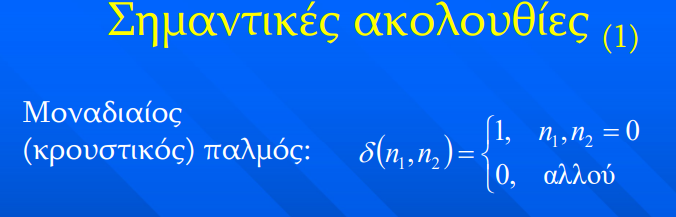

Η συνάρτηση point spread (PSF) περιγράφει την απόκριση ενός συστήματος απεικόνισης σε μια σημειακή πηγή ή ένα σημείο. Ένας πιο γενικός όρος για το PSF είναι η παλμική απόκριση ενός συστήματος, ενώ το PSF είναι η παλμική απόκριση ενός εστιασμένου οπτικού συστήματος.

Προκύπτει ένα θόλωμα στην εικόνα αφού ο FFT της κρουστικής απόκρισης της PSF μας δείχνει ότι πρόκειται για κα΄ποιο είδος χαμηλοπερατού φίλτρου. 

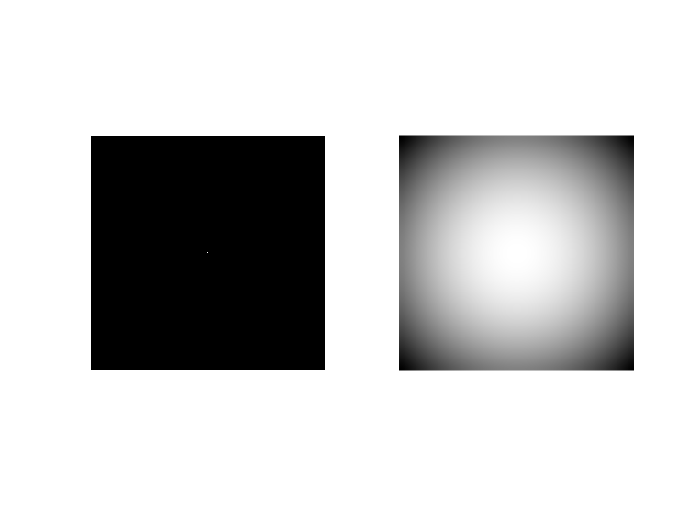

kroustiki=zeros(256,256);
kroustiki(128,128)=255;
Y=psf(kroustiki);
Y_2dfft=fft2(Y);
kroustiki_apok_suxn=fftshift(Y_2dfft);

figure();
subplot(1,2,1);
imshow(kroustiki);
subplot(1,2,2);
out=(10*log( abs(fftshift(Y_2dfft)) ) );
min1=min(out,[],'all');
max1=max(out,[],'all');
imshow(out,[min1,max1])

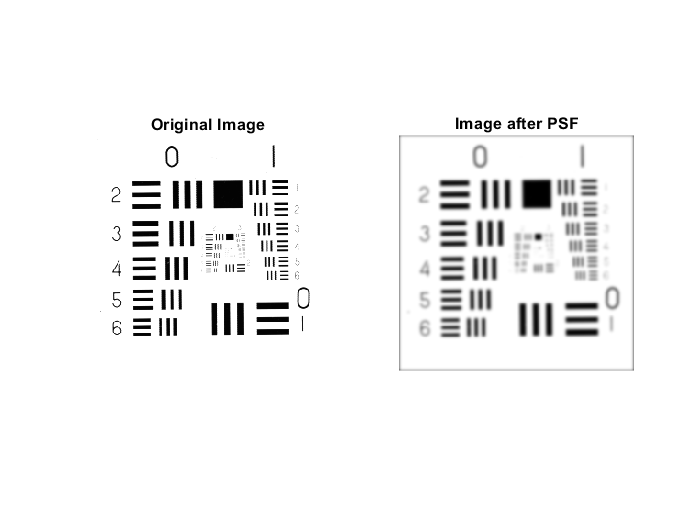

x = imread('images\4\chart.tiff');
Xout=psf(x);
figure();
subplot(121)
imshow(x);
title(sprintf("Original Image"));
subplot(1,2,2)
min1=min(Xout,[],'all');
max1=max(Xout,[],'all');
imshow(Xout,[min1,max1]);
title(sprintf("Image after PSF"));

figure()

SOURCE

https://www.owlnet.rice.edu/~elec539/Projects99/BACH/proj2/inverse.html

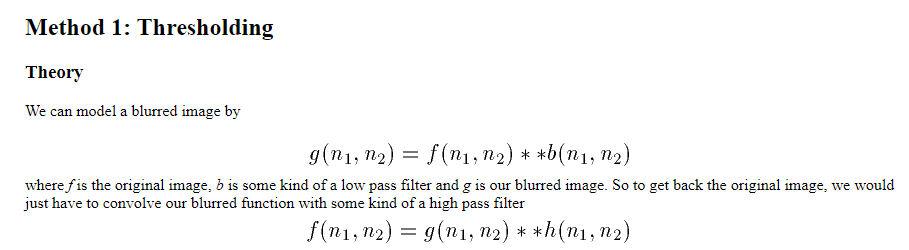

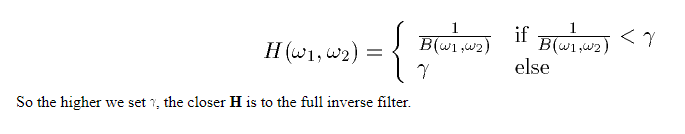

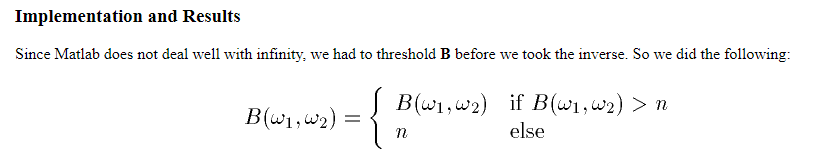

Πραγματοποιούμε την διαδικασία για τις διάφορες τιμές του gamma και βλέπουμε το μέσο τετραγωνικό σφάλμα το οποίο προκύπτει μεταξύ της αρχικής εικόνας (χωρίς θόρυβο) και του αποτελέσματος για διάφορες τιμές κατωφλιού. Η τιμή του γαμμα που δίνει το καλύτερο μέσο τετραγωνικό σφάλμα είναι και αυτή που θεωρούμε ως την καλύτερη αναπαράσταση.

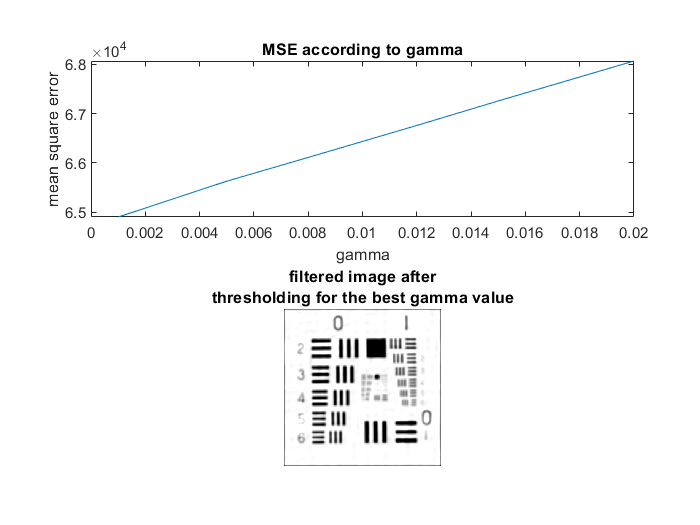

Xout_2dfft=fftshift(fft2(Xout));
blurred_x=Xout_2dfft;
B=zeros(size(kroustiki_apok_suxn,1),size(kroustiki_apok_suxn,2));
H=zeros(size(B,1),size(B,2));
gamma=[0.001 0.005 0.008  0.012 0.015  0.02 ] ;
best_mse=Inf;
MSE_mat=[];
x=double(x);
for k=1:length(gamma)
    for i=1:size(B,1)
        for j=1:size(B,2)
            if kroustiki_apok_suxn(i,j)>1/gamma(k)
                B(i,j)=kroustiki_apok_suxn(i,j);
            
            else 
                B(i,j)=1/gamma(k);
            end
            
        end
    end

    for i=1:size(B,1)
        for j=1:size(B,2)
            if 1/B(i,j)<gamma(k)
                H(i,j)=1/B(i,j);
            else 
                H(i,j)=gamma(k);
            end
        end
    end

    x_filtered_2dfft=blurred_x.*H;
    x_filtered=ifft2(ifftshift(x_filtered_2dfft));
    MSE=0;
    for p=1:256
        for m=1:256
            MSE=(x(i,j)-x_filtered(i,j))^2+MSE;
        end
    end
    MSE=MSE/(256*256);
    if MSE<best_mse
        best_mse=MSE;
        gamma_best=gamma(k);
        x_filtered_best=x_filtered;
    end
    MSE_mat=[MSE_mat MSE];
end
figure()
subplot(2,1,1)
plot(gamma,MSE_mat);
title('MSE according to gamma')
xlabel('gamma')
ylabel('mean square error')
subplot(2,1,2);
imshow(x_filtered_best)
title({"filtered image after" ; "thresholding for the best gamma value"})